# Optimierung für Industrielogistiker

## Übungsaufgabe 7

Programmieren Sie das Nelder-Mead-Verfahren aus. Benützen Sie dafür den in der beigefügten Datei stehenden Code.

(Es steht Ihnen frei zu wählen, welche Variante des Algorithmus Sie ausporgrammieren; Sie müssen also die Parameter ALPHA, BETA und GAMMA, die in der im Skriptum vorgestellten Version des Algorithmus vorkommen, nicht benützen!)

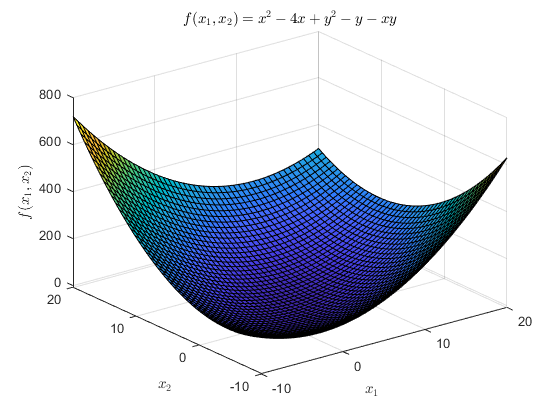

clear variablse;
clc;

f = @(x, y) x.^2 - 4 * x + y.^2 - y - x .* y;
x = linspace(-10, 20, 50);
y = linspace(-10, 20, 50);
[X, Y] = meshgrid(x, y);
Z = f(X, Y);
surf(X, Y, Z);
title('$f(x_1, x_2) = x^2 - 4 x + y^2 - y - x y$', 'interpreter', 'latex');
xlabel('$x_1$', 'interpreter', 'latex');
ylabel('$x_2$', 'interpreter', 'latex');
zlabel('$f(x_1, x_2)$', 'interpreter', 'latex');


EPSILON = 1e-3;
MAX_NUMBER_OF_ITERATIONS = 10000;
f = @(x) x(1).^2 - 4 * x(1) + x(2).^2 - x(2) - x(1) .* x(2);
ALPHA = 2;
BETA = 0.5

BETA = 0.5000

GAMMA = 5 / 2;
X_0 = [0; 0]

X_0 =      0
     0


[x, numberofiterations] = neldermeadalgorithm(true, f, X_0, ALPHA, BETA, GAMMA, EPSILON, MAX_NUMBER_OF_ITERATIONS);
disp(['x:                    [', num2str(x', '%.8f '), ']']);
disp(['number of iterations: ', num2str(numberofiterations)]);

function [x, numberofiterations] = neldermeadalgorithm(MINIMIZE, f, X_0, ALPHA, BETA, GAMMA, EPSILON, MAX_NUMBER_OF_ITERATIONS)
    x = X_0;
    numberofiterations = 0;
    n = 2; % Anzahl Veränderlichen 
    h = 0.5;
    
    [x_h, x_s, x_c] = defineStartPoints(x, h, n);
    
    for i=0:MAX_NUMBER_OF_ITERATIONS
        x_0 = (1 + ALPHA) * x_c - ALPHA * x_h;
        
        y_1 = f(x);
        y_0 = f(x_0);
        y_s = f(x_s);
        y_h = f(x_h);
        
        if y_1 <= y_0 && y_0 <= y_s 
            x_h = x_0;
            continue;
        end
        
        if y_0 < y_1
            x_00 = GAMMA * x_0 + (1 - GAMMA) * x_c;
            y_00 = f(x_00);
            
            if y_00 < y_1
                x_h = x_00;             
            else 
                x_h = x_0;                
            end
            
            continue;
        end
        
        if y_0 < y_h
            x_00 = BETA * x_0 + (1 - BETA) * x_c;
            y_00 = f(x_00);
            if y_00 < y_h && y_00 < y_0
                x_h = x_00;
                continue;
            elseif y_00 >= y_h || y_00 > y_0
                % Neue definition des Suchbereichs
                h = h/2;
                [x_h, x_s, x_c] = defineStartPoints(x, h, n);
            end
        else 
            x_00 = BETA * x_h + (1 - BETA) * x_c;
            y_00 = f(x_00);
            if y_00 < y_h && y_00 < y_0
                x_h = x_00;
                continue;
            elseif y_00 >= y_h || y_00 > y_0
                % Neue definition des Suchbereichs
                h = h/2;
                [x_h, x_s, x_c] = defineStartPoints(x, h, n);
            end
        end       
    end
end

function [x_h, x_s, x_c] = defineStartPoints(x, h, n)
    x_list = [x];
    for i = 1:n
        x_i = x + h * eig(i);
        x_list = [x_list, x_i];
    end
    
    highestValues = maxk(transpose(x_list), 2);
    x_h = highestValues(1, :);
    x_s = highestValues(2, :);

    sum = [0; 0];
    for i=1:n+1
        x_value = x_list(:, i);
        
        if x_value == x_h 
            continue;
        end
        
        sum = sum + x_value;
    end
    
    x_c = (1/n)*sum;
end